# Emmanuelle Chaigneau

# Serge Charpak Laboratory

# Figure 8 (S1) Dual color ratiometric measurements

# Correction of Time Dependent Change in plasmatic Concentration of Fluorophores (TDCCF) 

## Parameters

Fig8TitleFontsize = 14 ;
Fig8LegendFontsize = 10 ;
Fig8AxisLabelFontsize = 12 ;
Fig8Linewidth = 2 ;

Figure8 = figure;
Figure8.Position = [10 10 600 300] ;
Figure8Layout = tiledlayout(2,3);
Figure8Layout.Padding = 'tight';

## Load data 

load FRatioVsTimeAndDepth_2024Oct11.mat

Depth = FRatioVsTimeAndDepth(:,1) ;

Time1 = FRatioVsTimeAndDepth(:,2) ;
Time2 = FRatioVsTimeAndDepth(:,3) ;
Time3 = FRatioVsTimeAndDepth(:,4) ; 

fitresultCap1 =      General model:
     fitresultCap1(x) = exp(x/T)
     Coefficients (with 95% confidence bounds):
       T =      -352.3  (-418.1, -286.5)

gof = struct with fields:
           sse: 3.5284e-04
       rsquare: 0.9763
           dfe: 3
    adjrsquare: 0.9763
          rmse: 0.0108


Time4 = FRatioVsTimeAndDepth(1,5) ;


Tau = -352.2858

FR1 = FRatioVsTimeAndDepth(:,6) / FRatioVsTimeAndDepth(1,6) ;
FR2 = FRatioVsTimeAndDepth(:,7) / FRatioVsTimeAndDepth(1,6) ;
FR3 = FRatioVsTimeAndDepth(:,8) / FRatioVsTimeAndDepth(1,6) ;
FR4 = FRatioVsTimeAndDepth(1,9) / FRatioVsTimeAndDepth(1,6) ;

TimeConcat = [Time1 ; Time2 ; Time3 ; Time4] ;
DepthConcat = [Depth; Depth; Depth; Depth(1)] ;
FRConcat = [FR1 ; FR2 ; FR3 ; FR4] / FRatioVsTimeAndDepth(1,6) ;

TimeCap1 = FRatioVsTimeAndDepth(1,2:5) ;
FRCap1 = FRatioVsTimeAndDepth(1,6:9) / FRatioVsTimeAndDepth(1,6) ;


## Fit FRatio versus Time for Capillary on surface

### Set up fittype and options for Time fitting.

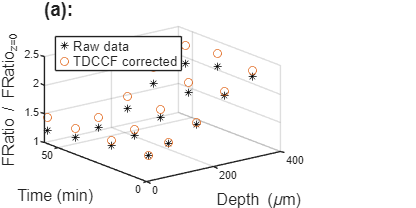

ft = fittype( 'exp(x/T)', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.StartPoint = -100;

[xData, yData] = prepareCurveData(TimeCap1, FRCap1);
[fitresultCap1, gof] = fit( xData, yData, ft, opts)
fitcoeffvalsCap1= coeffvalues(fitresultCap1);
Tau = fitcoeffvalsCap1(1)


### Calculates corrected data 

TDCCFcorFRConcat = exp(-TimeConcat./Tau) .*FRConcat;


## Panel a : comparison raw data corrected data

nexttile([2 2])

hraw = scatter3( DepthConcat, TimeConcat, FRConcat, 'k', '*' );
hold on
hcorrected = scatter3( DepthConcat, TimeConcat, TDCCFcorFRConcat );
hold off

legend("Raw data", "TDCCF corrected", 'Location', 'NorthWest', 'Fontsize', Fig8LegendFontsize) ;
xlabel("Depth (\mum)", "FontSize", Fig8AxisLabelFontsize) ;
ylabel("Time (min)", "FontSize", Fig8AxisLabelFontsize) ;
zlabel(" FRatio / FRatio_{z=0} ", "FontSize", Fig8AxisLabelFontsize) ;
grid on

title('(a):', 'FontSize', Fig8TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';


## Panel b : Fit FRatio versus Time for Capillary on surface

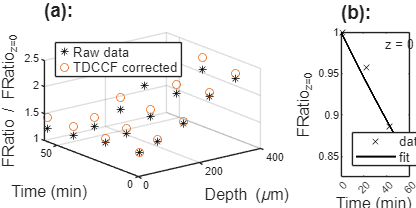

nexttile([2 1])


hDataCap1 = plot(TimeCap1, FRCap1,'kx');
hold on
hfitCap1 = plot( fitresultCap1, 'k-');
hold off

legend('data', 'fit','Location', 'SouthWest', "FontSize", Fig8LegendFontsize);
xlabel("Time (min) ", "FontSize", Fig8AxisLabelFontsize)
ylabel(" FRatio_{z=0} ", "FontSize", Fig8AxisLabelFontsize)

axis([0 60 0.825 1]);
xticks([0 20 40 60]);
yticks([0.85 0.9 0.95 1]);

text(38, 0.985,'z = 0')

title('(b):', 'FontSize', Fig8TitleFontsize)
ax = gca;
ax.TitleHorizontalAlignment = 'left';
